clc;
clear;
close all;

disp('--- Gear Ratio and Speed Analysis ---');

--- Gear Ratio and Speed Analysis ---



% User input
N1 = input('Enter number of teeth on driver gear (N1): ');
N2 = input('Enter number of teeth on driven gear (N2): ');

omega1 = input('Enter input speed (RPM): ');

% Calculation
omega2 = omega1 * (N1 / N2);
gear_ratio = N2 / N1;

% Display results
fprintf('\n--- Results ---\n');


--- Results ---


fprintf('Gear Ratio = %.2f\n', gear_ratio);

Gear Ratio = 0.80


fprintf('Output Speed = %.2f RPM\n', omega2);

Output Speed = 10000.00 RPM


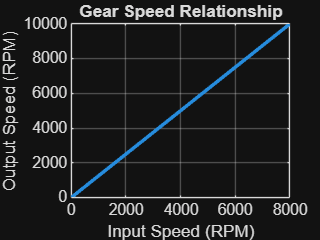


% Optional: Generate graph
choice = input('\nDo you want to see speed variation graph? (y/n): ', 's');

if choice == 'y'
    omega1_range = linspace(0, omega1, 50);
    omega2_range = omega1_range .* (N1 / N2);

    figure;
    plot(omega1_range, omega2_range, 'LineWidth', 2);
    grid on;

    xlabel('Input Speed (RPM)');
    ylabel('Output Speed (RPM)');
    title('Gear Speed Relationship');
end